clear
clc
close all

[main,sub] = getAgreement('/media/ben/Extreme SSD/analysisData/added_aligned/binnedData/Models/UpdtaedSynced')

FRFiles = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


FeaturesFiles = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


main = struct with fields:
     cosineAll: [5119×1 double]
        predFR: [5119×4 double]
      predFeat: [5119×4 double]
    truelabels: {5119×1 cell}
      FRlabels: {5119×1 cell}
    FeatLabels: {5119×1 cell}
    FVB103_757: [1×1 struct]
     corrClass: [7×4 double]
         corrP: [7×4 double]
            MI: [0.7202 0.6840 0.6023 1.1297 1.0888 0.4540 0.3789]
          corr: [0.7535 0.2975 -0.1324 0.4890 0.4138 0.6636 0.4404]
    FVB103_849: [1×1 struct]
    FVB108_986: [1×1 struct]
    FVB109_102: [1×1 struct]
    FVB109_904: [1×1 struct]
    FVB110_600: [1×1 struct]
    FVB111_715: [1×1 struct]


sub = struct with fields:
     cosineAll: [5074×1 double]
        predFR: [2537×3 double]
      predFeat: [2537×3 double]
    truelabels: {2537×1 cell}
      FRlabels: {2537×1 cell}
    FeatLabels: {2537×1 cell}
    FVB103_757: [1×1 struct]
     corrClass: [7×3 double]
         corrP: [7×3 double]
            MI: [0.2070 0.0945 0.1729 0.0416 0.1761 1.0273 -0.0376]
          corr: [0.3340 0.3544 -0.3480 0.2536 0.1798 1 0.0207]
    FVB103_849: [1×1 struct]
    FVB108_986: [1×1 struct]
    FVB109_102: [1×1 struct]
    FVB109_904: [1×1 struct]
    FVB110_600: [1×1 struct]
    FVB111_715: [1×1 struct]


[shuffleMain,shuffleSub] = getAgreement('/media/ben/Extreme SSD/analysisData/added_aligned/binnedData/Models/UpdtaedSynced/shuffled')

FRFiles = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


FeaturesFiles = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


shuffleMain = struct with fields:
     cosineAll: [5119×1 double]
        predFR: [5119×4 double]
      predFeat: [5119×4 double]
    truelabels: {5119×1 cell}
      FRlabels: {5119×1 cell}
    FeatLabels: {5119×1 cell}
    FVB103_757: [1×1 struct]
     corrClass: [7×4 double]
         corrP: [7×4 double]
            MI: [0.0518 0.0029 0.0204 0.0119 0.0137 0.0673 0.0315]
          corr: [0.1644 0.0176 -0.0020 -0.0513 0.1057 -0.1254 0.0209]
    FVB103_849: [1×1 struct]
    FVB108_986: [1×1 struct]
    FVB109_102: [1×1 struct]
    FVB109_904: [1×1 struct]
    FVB110_600: [1×1 struct]
    FVB111_715: [1×1 struct]


shuffleSub = struct with fields:
     cosineAll: [5074×1 double]
        predFR: [2537×3 double]
      predFeat: [2537×3 double]
    truelabels: {2537×1 cell}
      FRlabels: {2537×1 cell}
    FeatLabels: {2537×1 cell}
    FVB103_757: [1×1 struct]
     corrClass: [7×3 double]
         corrP: [7×3 double]
            MI: [-0.0074 0.0610 -0.0076 0.0162 -0.0132 1.0526 -0.0186]
          corr: [0.0726 0.1033 0.0161 -0.0145 2.3899e-04 1 0.0300]
    FVB103_849: [1×1 struct]
    FVB108_986: [1×1 struct]
    FVB109_102: [1×1 struct]
    FVB109_904: [1×1 struct]
    FVB110_600: [1×1 struct]
    FVB111_715: [1×1 struct]


FRsuccess = strcmp(main.truelabels,main.FRlabels);
Featuresuccess = strcmp(main.truelabels,main.FeatLabels)

Featuresuccess = 5119×1 logical array
   0
   0
   0
   1
   1
   1
   0
   0
   0
   0




FRsuccessSub = strcmp(sub.truelabels,sub.FRlabels);
FeaturesuccessSub = strcmp(sub.truelabels,sub.FeatLabels)

FeaturesuccessSub = 2537×1 logical array
   0
   1
   0
   1
   1
   1
   0
   1
   0
   0


FRsuccessShuffle = strcmp(shuffleMain.truelabels,shuffleMain.FRlabels);
FeauresuccessShuffle = strcmp(shuffleMain.truelabels,shuffleMain.FeatLabels);


FRsuccessSubShuffle = strcmp(shuffleSub.truelabels,shuffleSub.FRlabels);
FeaturesuccessSubShuffle = strcmp(shuffleSub.truelabels,shuffleSub.FeatLabels);

shuffle_failure = and(FRsuccessShuffle == 0,FeauresuccessShuffle == 0)

shuffle_failure = 5119×1 logical array
   0
   1
   0
   0
   1
   0
   1
   0
   1
   1


shuffle_failure_sub = and(FRsuccessSubShuffle == 0,FeaturesuccessSubShuffle == 0)

shuffle_failure_sub = 2537×1 logical array
   0
   0
   0
   1
   1
   1
   1
   0
   1
   0


%samples = 'all'
%samples = 'fail'
samples = 'aud'

samples = 'aud'

%samples = 'failXOR'
%samples = 'FRfailXOR'
%samples = 'FeatureXOR'

switch samples
    case 'all'
        FRlabels = main.FRlabels;
        featureLabels = main.FeatLabels;
        scoresFeatures = main.predFeat;
        scoresFR = main.predFR;

        FRlabelsSub = sub.FRlabels;
        featureLabelsSub = sub.FeatLabels;
        scoresFeaturesSub = sub.predFeat;
        scoresFRSub = sub.predFR;
        mainK = 0.7017;
        shuffleK = 0.0667;
        subK = 0.4830;
        subShuffleK = 0.1916;
        mainCM = 'allPredicitonCM.svg';
        mainCC = 'allPredictionScoresCC.svg'
        subCM = 'allPredicitonCM_sub.svg';
        subCC = 'allPredictionScoresCC_sub.svg'
        mainBP = 'allBarplot.svg'
        subBP = 'allBarplotSub.svg'
        for mI = 1:4
            indNan = ~isnan(scoresFR(:,mI));
            [rMainAll(mI),pMainAll(mI)] = corr(scoresFR(indNan,mI),scoresFeatures(indNan,mI));
        end
    case 'fail'
        bothFailure = and(FRsuccess == 0,Featuresuccess == 0)
        bothFailureSub = and(FRsuccessSub == 0,FeaturesuccessSub == 0)
        FRlabels = main.FRlabels(bothFailure);
        featureLabels = main.FeatLabels(bothFailure);
        scoresFeatures = main.predFeat(bothFailure,:);
        scoresFR = main.predFR(bothFailure,:);

        FRlabelsSub = sub.FRlabels(bothFailureSub);
        featureLabelsSub = sub.FeatLabels(bothFailureSub);
        scoresFeaturesSub = sub.predFeat(bothFailureSub,:);
        scoresFRSub = sub.predFR(bothFailureSub,:);
        mainCM = 'failPredicitonCM.svg';
        mainCC = 'failPredictionScoresCC.svg'
        subCM = 'failPredicitonCM_sub.svg';
        subCC = 'failPredictionScoresCC_sub.svg'
        mainBP = 'failBarplot.svg'
        subBP = 'failBarplotSub.svg'        
        mainK = 0.6601;
        shuffleK = 0.1885;
        subK = 0.7219;
        subShuffleK = 0.4187;
        for mI = 1:4
            indNan = ~isnan(scoresFR(:,mI));
            [rMainFail(mI),pMainFail(mI)] = corr(scoresFR(indNan,mI),scoresFeatures(indNan,mI));
        end
    case 'aud'
        bothFailure = Featuresuccess == 1;
        bothFailureSub = FeaturesuccessSub == 1;
        FRlabels = main.FRlabels(bothFailure);
        featureLabels = main.FeatLabels(bothFailure);
        scoresFeatures = main.predFeat(bothFailure,:);
        scoresFR = main.predFR(bothFailure,:);
        mainK = 0.813;
        shuffleK = 0.072;
        kappaCI = 0.0072/2;
        shuffleCI = 0.0365/2;
        FRlabelsSub = sub.FRlabels(bothFailureSub);
        featureLabelsSub = sub.FeatLabels(bothFailureSub);
        scoresFeaturesSub = sub.predFeat(bothFailureSub,:);
        scoresFRSub = sub.predFR(bothFailureSub,:);

end

confusionM = confusionmat(featureLabels,FRlabels,"Order",{'Aluminum','Attenuated','No object','No whisking'})

confusionM =          861          43          34          26
          29         534         104          13
          51         132         622          42
          34          32          45        1864


confusionMS = confusionmat(featureLabelsSub,FRlabelsSub,"Order",{'NW_Aluminum','NW_Attenuated','NW_No object'})

confusionMS =    659   166   167
   153   473   142
   132   110   535


 kappa(confusionM)

UNWEIGHTED COHEN'S KAPPA
--------------------------------------------------------------------------------
Observed agreement (po) = 0.8690
Random agreement (pe) = 0.2992
Agreement due to true concordance (po-pe) = 0.5698
Residual not random agreement (1-pe) = 0.7008
Cohen's kappa = 0.8131
kappa error = 0.0072
kappa C.I. (alpha = 0.0500) = 0.7990     0.8272
Maximum possible kappa, given the observed marginal frequencies = 0.9770
k observed as proportion of maximum possible = 0.8322
Perfect agreement
z (k/kappa error) = 112.8708    p = 0.0000
Reject null hypotesis: observed agreement is not accidental
 


shuffleFeatures = strcmp(shuffleMain.truelabels,shuffleMain.FeatLabels)

shuffleFeatures = 5119×1 logical array
   0
   0
   0
   1
   0
   1
   0
   0
   0
   0


kappa(confusionmat(shuffleMain.FeatLabels(shuffleFeatures),shuffleMain.FRlabels(shuffleFeatures),"Order",{'Aluminum','Attenuated','No object','No whisking'}))

UNWEIGHTED COHEN'S KAPPA
--------------------------------------------------------------------------------
Observed agreement (po) = 0.3045
Random agreement (pe) = 0.2503
Agreement due to true concordance (po-pe) = 0.0542
Residual not random agreement (1-pe) = 0.7497
Cohen's kappa = 0.0723
kappa error = 0.0186
kappa C.I. (alpha = 0.0500) = 0.0358     0.1088
Maximum possible kappa, given the observed marginal frequencies = 0.9436
k observed as proportion of maximum possible = 0.0766
Slight agreement
z (k/kappa error) = 3.8809    p = 0.0001
Reject null hypotesis: observed agreement is not accidental
 


rMain = [rMainAll;rMainFail]

Unrecognized function or variable 'rMainFail'.

colorPallete
pMainAll

pMainAll =      0     0     0     0


pMainFail

pMainFail = 1.0e-07 *

    0.1501    0.0000    0.0000    0.0000


titles = {'Aluminum','Attenuated','No object','No whisking'}

titles = 1×4 cell array
    {["'Aluminum'"]}    {["'Attenuated'"]}    {["'No object'"]}    {["'No whisking'"]}


Legends = {'Aluminum','Attenuated','No object','No whisking'}

Legends = 1×4 cell array
    {'Aluminum'}    {'Attenuated'}    {'No object'}    {'No whisking'}


h = figure;
for i = 1:4
    if i < 3
        k = i;
    else
        k = i+1;
    end
subplot(2,6,[2*k-1,2*k])
hold on
rateBars = confusionM(i,:)./sum(confusionM(i,:));
b = bar(confusionM(i,:)./sum(confusionM(i,:)));
b.FaceColor = 'flat';
b.CData(1,:) = colorBen.aluminum;
b.CData(2,:) = colorBen.muted;
b.CData(3,:) = colorBen.non;
b.CData(4,:) = colorBen.noWhisking;

set(gca,'FontSize',20)
set(gca,'FontName','SansSerif')
ylim([0 1])
xticklabels('')
title(titles{i},'FontWeight','normal')
if i==1
    ylabel('FR prediction')
elseif i == 3
    ylabel('FR prediction')
elseif i== 2
    ha = area(rateBars,nan(numel(rateBars)))
    ha(1).FaceColor = colorBen.aluminum;
    ha(2).FaceColor = colorBen.muted;
    ha(3).FaceColor = colorBen.non;
    ha(4).FaceColor = colorBen.noWhisking;
    legend([{''},Legends],'Box','off','Position',[0.5578 0.7795 0.1862 0.1506])
end
end

ha =   1×4 Area array:

    Area    Area    Area    Area


subplot(2,6,[6,12])
hold on
bk = bar([mainK;shuffleK])

bk =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2]
        YData: [0.8130 0.0720]

  Show all properties


bk.FaceColor = 'flat';
bk.CData(1,:) = [0 0 0];
bk.CData(2,:) = [0.75 0.75 0.75];
ylabel("agreement (cohen's kappa)")
set(gca,'FontSize',20)
set(gca,'FontName','SansSerif')
ha = area([mainK;shuffleK],nan(2))

ha =   1×2 Area array:

    Area    Area


ha(1).FaceColor = [0 0 0];
ha(2).FaceColor = [0.75 0.75 0.75];
%errorbar([mainK shuffleK],[kappaCI shuffleCI],'Color',[0.9 0.9 0.9],'LineStyle','none')
ylim([0 0.85])
xticklabels('')
legend({'','Model','Shuffle'},'Box','off','Position',[0.8528 0.8536 0.1276 0.0774])


set(gcf,'Position',[2267,71,1058,807]);

cd /media/ben/'Extreme SSD'/Thesis/figures/Fig4-classifiars/ModelComparisons/

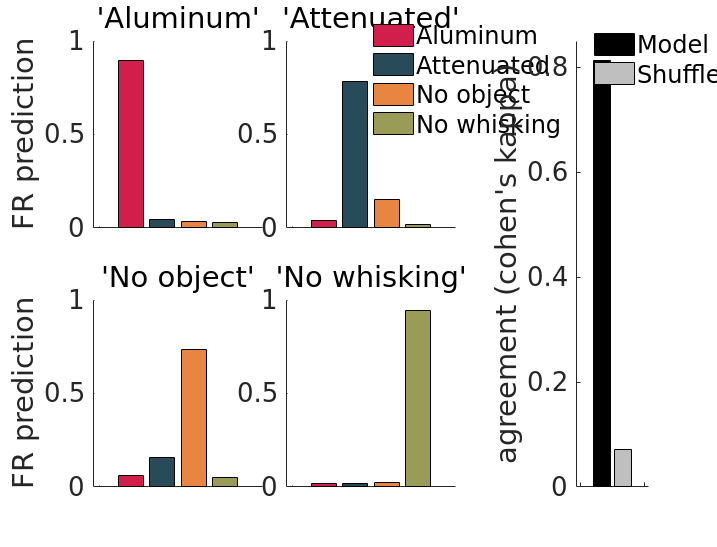

saveas(h,'sound Correct.svg','svg')

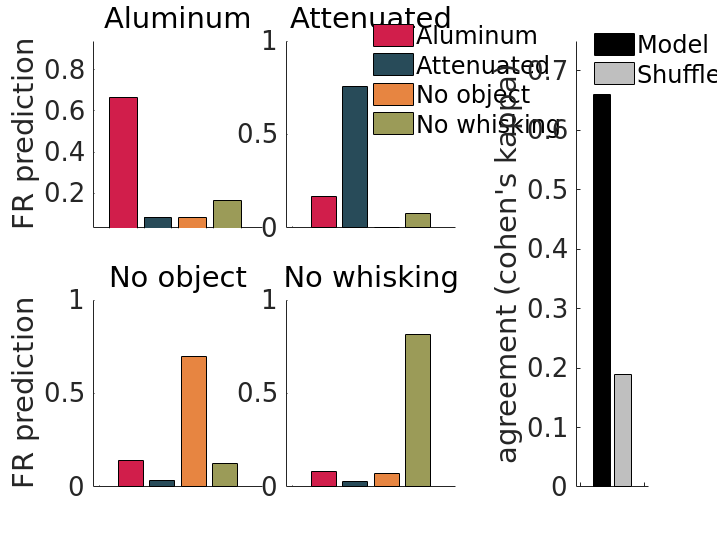

saveas(h,mainBP,'svg')

titles = {'NW Aluminum','NW Attenuated','NW No object'}

titles = 1×3 cell array
    {'NW Aluminum'}    {'NW Attenuated'}    {'NW No object'}


h = figure;
for i = 1:3
    if i < 3
        k = i;
    else
        k = i+1;
    end
subplot(2,6,[2*k-1,2*k])
hold on
rateBars = confusionMS(i,:)./sum(confusionMS(i,:));
b = bar(confusionMS(i,:)./sum(confusionMS(i,:)));
b.FaceColor = 'flat';
b.CData(1,:) = colorBen.aluminum;
b.CData(2,:) = colorBen.muted;
b.CData(3,:) = colorBen.non;
%b.CData(4,:) = colorBen.noWhisking;

set(gca,'FontSize',20)
set(gca,'FontName','SansSerif')
ylim([0 1])
xticklabels('')
title(titles{i},'FontWeight','normal')
if i==1
    ylabel('FR prediction')
elseif i == 3
    ylabel('FR prediction')
elseif i== 2
    ha = area(rateBars,nan(numel(rateBars)))
    ha(1).FaceColor = colorBen.aluminum;
    ha(2).FaceColor = colorBen.muted;
    ha(3).FaceColor = colorBen.non;
    %ha(4).FaceColor = colorBen.noWhisking;
    legend([{''},titles],'Box','off','Position',[0.5578 0.7795 0.1862 0.1506])
end
end

ha =   1×3 Area array:

    Area    Area    Area


subplot(2,6,[6,12])
hold on
bk = bar([subK;subShuffleK])

bk =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2]
        YData: [0.7219 0.4187]

  Show all properties


bk.FaceColor = 'flat';
bk.CData(1,:) = [0 0 0];
bk.CData(2,:) = [0.75 0.75 0.75];
ylabel("agreement (cohen's kappa)")
set(gca,'FontSize',20)
set(gca,'FontName','SansSerif')
ha = area([mainK;shuffleK],nan(2))

ha =   1×2 Area array:

    Area    Area


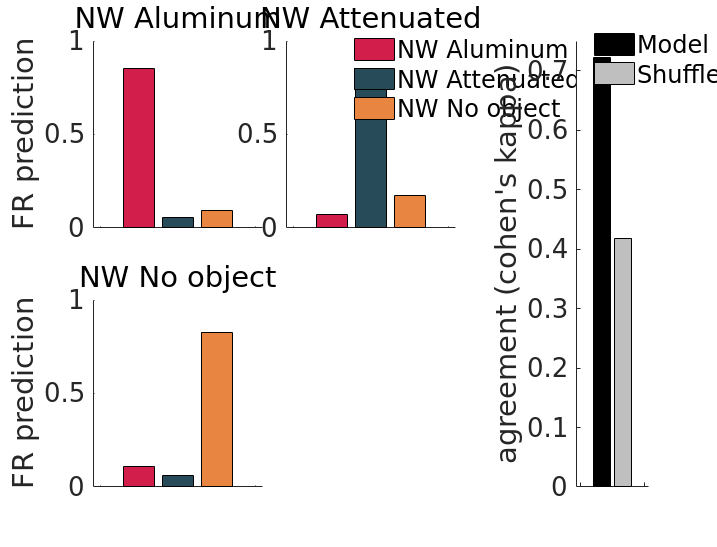

ha(1).FaceColor = [0 0 0];
ha(2).FaceColor = [0.75 0.75 0.75];
ylim([0 0.75])
xticklabels('')
legend({'','Model','Shuffle'},'Box','off','Position',[0.8528 0.8536 0.1276 0.0774])


set(gcf,'Position',[2267,71,1058,807]);

cd /media/ben/'Extreme SSD'/Thesis/figures/Fig4-classifiars/ModelComparisons/
saveas(h,subBP,'svg')

for sI = 1:3
    [rSub(sI),pSub(sI)] = corr(scoresFRSub(:,sI),scoresFeaturesSub(:,sI));
end

colorsBars = {colorBen.aluminum,colorBen.muted,colorBen.non,colorBen.noWhisking}

colorsBars = 1×4 cell array
    {[0.8190 0.1170 0.2925]}    {[0.1560 0.2925 0.3471]}    {[0.9048 0.5226 0.2535]}    {[0.6078 0.6078 0.3451]}


h = figure;
b = bar(rMainAll)

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4]
        YData: [0.8687 0.7268 0.7409 0.8754]

  Show all properties


b(1).FaceColor = 'flat';
b(1).CData(1,:) = colorBen.aluminum

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4]
        YData: [0.8687 0.7268 0.7409 0.8754]

  Show all properties


b(1).CData(4,:) = colorBen.noWhisking

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4]
        YData: [0.8687 0.7268 0.7409 0.8754]

  Show all properties


b(1).CData(2,:) = colorBen.muted

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4]
        YData: [0.8687 0.7268 0.7409 0.8754]

  Show all properties


b(1).CData(3,:) = colorBen.non

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4]
        YData: [0.8687 0.7268 0.7409 0.8754]

  Show all properties


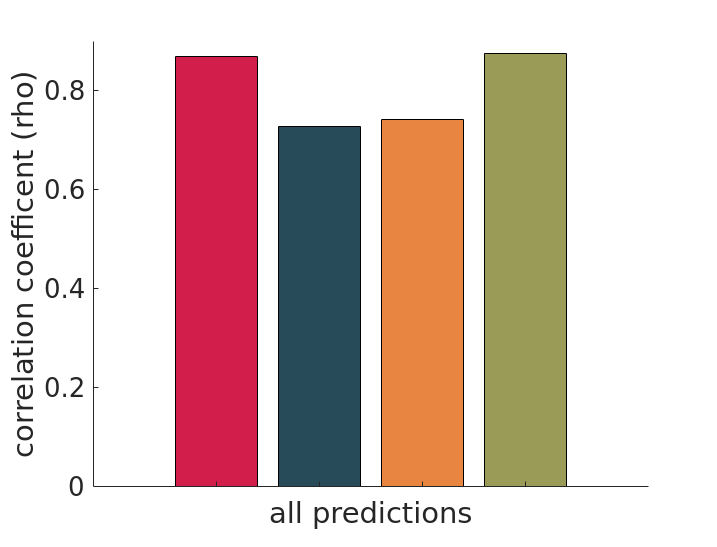

xticklabels('')
xlabel('all predictions')
ylabel('correlation coefficent (rho)')
set(gca,'FontSize',20)
set(gca,'FontName','SansSerif')
ylim([0 0.9])
box off
set(gcf,'Position',[2267,71,1058,807]);

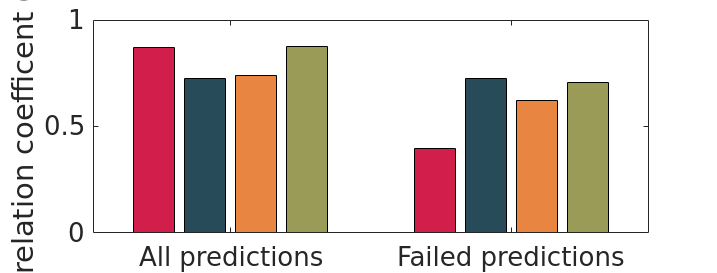

cd /media/ben/'Extreme SSD'/Thesis/figures/Fig4-classifiars/ModelComparisons/
saveas(h,'correlationsA.svg','svg')

b(1).FaceColor = 'flat';
b(1).CData(1,:) = colorBen.aluminum
b(1).CData(4,:) = colorBen.noWhisking
b(1).CData(2,:) = colorBen.muted
b(1).CData(3,:) = colorBen.non
b(2).FaceColor = 'flat';
b(2).CData(1,:) = lightenColor(colorBen.aluminum,0.3)
b(2).CData(4,:) = lightenColor(colorBen.noWhisking,0.3)
b(2).CData(2,:) = lightenColor(colorBen.muted,0.3)
b(2).CData(3,:) = lightenColor(colorBen.non,0.3)

cd /media/ben/'Extreme SSD'/Thesis/figures/Fig4-classifiars/ModelComparisons/
saveas(h,mainCC,'svg')

h = figure;
b = bar(rSub)

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3]
        YData: [0.6128 0.6810 0.7383]

  Show all properties


b.FaceColor = 'flat';
b.CData(1,:) = colorBen.aluminum

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3]
        YData: [0.6128 0.6810 0.7383]

  Show all properties


b.CData(2,:) = colorBen.muted

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3]
        YData: [0.6128 0.6810 0.7383]

  Show all properties


b.CData(3,:) = colorBen.non

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3]
        YData: [0.6128 0.6810 0.7383]

  Show all properties


xticklabels({'NW Aluminum','NW Attenuated','NW No object'})
ylim([0 0.75])
ylabel('correlation coefficent (rho)')
set(gca,'FontSize',20)
set(gca,'FontName','SansSerif')

cd /media/ben/'Extreme SSD'/Thesis/figures/Fig4-classifiars/ModelComparisons/
saveas(h,subCC,'svg')

titles = {'Alimunim prediction', 'Attenuated prediction', 'no object prediction','no whisking prediction'}

titles = 1×4 cell array
    {'Alimunim prediction'}    {'Attenuated prediction'}    {'no object prediction'}    {'no whisking prediction'}


colorPallete
colors = {colorBen.aluminum,colorBen.muted,colorBen.non,colorBen.noWhisking}

colors = 1×4 cell array
    {[0.8190 0.1170 0.2925]}    {[0.1560 0.2925 0.3471]}    {[0.9048 0.5226 0.2535]}    {[0.6078 0.6078 0.3451]}


h = figure;
confusionchart(featureLabels,FRlabels,"Normalization","column-normalized",'FontSize',22,'FontName','SansSerif')
xlabel('FR prediction')
ylabel('sound prediction')
set(gca,'FontSize',20)
set(gca,'FontName','SansSerif')

set(gcf,'Position',[2267,71,1058,807]);

cd /media/ben/'Extreme SSD'/Thesis/figures/Fig4-classifiars/ModelComparisons/
saveas(h,mainCM,'svg')

h = figure;
confusionchart(featureLabelsSub,FRlabelsSub,"Normalization","column-normalized",'FontSize',22,'FontName','SansSerif')
xlabel('FR prediction')
ylabel('sound prediction')
set(gca,'FontSize',20)
set(gca,'FontName','SansSerif')

set(gcf,'Position',[2267,71,1058,807]);

cd /media/ben/'Extreme SSD'/Thesis/figures/Fig4-classifiars/ModelComparisons/
saveas(h,subCM,'svg')

for i = 1:4
    figure;
    scatter(main.predFeat(:,i),main.predFR(:,i),'k')
    xnan = ~isnan(main.predFeat(:,i));
    ynan = ~isnan(main.predFR(:,i));
    r = corr(main.predFeat(xnan,i),main.predFR(ynan,i))
    hold on
    for ii = 1:4
        scatter(main.predFeat(main.truelabels == ii,i),main.predFR(main.truelabels == ii,i),'filled','o','MarkerFaceColor',colors{ii},'MarkerFaceAlpha',0.3)
    end
    title(titles{i})
    xlabel('Sound prediction')
    ylabel('FR prediction')
    legend({'','Aluminum','Attenuated','No object','No whisking'})
    text(0.9,1.02,['rho = ',num2str(r,2)])

end


cd /media/ben/'Extreme SSD'/analysisData/added_aligned/binnedData/Models/UpdtaedSynced/shuffled/

FRFiles = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


FeaturesFiles = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


FRFiles = dir('*FR.mat')
FeaturesFiles = dir('*Features.mat')

% case 'failOR'
%         bothFailure = or(FRsuccess == 0,Featuresuccess == 0)
%         bothFailureSub = or(FRsuccessSub == 0,FeaturesuccessSub == 0)
%         FRlabels = main.FRlabels(bothFailure);
%         featureLabels = main.FeatLabels(bothFailure);
%         scoresFeatures = main.predFeat(bothFailure,:);
%         scoresFR = main.predFR(bothFailure,:);
% 
%         FRlabelsSub = sub.FRlabels(bothFailureSub);
%         featureLabelsSub = sub.FeatLabels(bothFailureSub);
%         scoresFeaturesSub = sub.predFeat(bothFailureSub,:);
%         scoresFRSub = sub.predFR(bothFailureSub,:);
%         mainCM = 'failOrPredicitonCM.svg';
%         mainCC = 'failOrPredictionScoresCC.svg'
%         subCM = 'failOrPredicitonCM_sub.svg';
%         subCC = 'failOrPredictionScoresCC_sub.svg'
%     case 'FeatureXOR'
%         bothFailure = and(FRsuccess == 0,Featuresuccess == 1)
%         bothFailureSub = and(FRsuccessSub == 0,FeaturesuccessSub == 1)
%         FRlabels = main.FRlabels(bothFailure);
%         featureLabels = main.FeatLabels(bothFailure);
%         scoresFeatures = main.predFeat(bothFailure,:);
%         scoresFR = main.predFR(bothFailure,:);
% 
%         FRlabelsSub = sub.FRlabels(bothFailureSub);
%         featureLabelsSub = sub.FeatLabels(bothFailureSub);
%         scoresFeaturesSub = sub.predFeat(bothFailureSub,:);
%         scoresFRSub = sub.predFR(bothFailureSub,:);
%         mainCM = 'FefailXOrPredicitonCM.svg';
%         mainCC = 'FefailXOrPredictionScoresCC.svg'
%         subCM = 'FefailXOrPredicitonCM_sub.svg';
%         subCC = 'FefailXOrPredictionScoresCC_sub.svg'
%     case 'FRfailXOR'
%         bothFailure = and(FRsuccess == 1,Featuresuccess == 0)
%         bothFailureSub = and(FRsuccessSub == 1,FeaturesuccessSub == 0)
%         FRlabels = main.FRlabels(bothFailure);
%         featureLabels = main.FeatLabels(bothFailure);
%         scoresFeatures = main.predFeat(bothFailure,:);
%         scoresFR = main.predFR(bothFailure,:);
% 
%         FRlabelsSub = sub.FRlabels(bothFailureSub);
%         featureLabelsSub = sub.FeatLabels(bothFailureSub);
%         scoresFeaturesSub = sub.predFeat(bothFailureSub,:);
%         scoresFRSub = sub.predFR(bothFailureSub,:);
%         mainCM = 'FRfailXOrPredicitonCM.svg';
%         mainCC = 'FRfailXOrPredictionScoresCC.svg'
%         subCM = 'FRfailXOrPredicitonCM_sub.svg';
%         subCC = 'FRfailXOrPredictionScoresCC_sub.svg'
%     case 'failXOR'
%         bothFailure = xor(FRsuccess == 0,Featuresuccess == 0)
%         bothFailureSub = xor(FRsuccessSub == 0,FeaturesuccessSub == 0)
%         FRlabels = main.FRlabels(bothFailure);
%         featureLabels = main.FeatLabels(bothFailure);
%         scoresFeatures = main.predFeat(bothFailure,:);
%         scoresFR = main.predFR(bothFailure,:);
% 
%         FRlabelsSub = sub.FRlabels(bothFailureSub);
%         featureLabelsSub = sub.FeatLabels(bothFailureSub);
%         scoresFeaturesSub = sub.predFeat(bothFailureSub,:);
%         scoresFRSub = sub.predFR(bothFailureSub,:);
%         mainCM = 'failXOrPredicitonCM.svg';
%         mainCC = 'failXOrPredictionScoresCC.svg'
%         subCM = 'failXOrPredicitonCM_sub.svg';
%         subCC = 'failXOrPredictionScoresCC_sub.svg'

function cosineS = getSimilarity(model1Scores,model2Scores)
nObservations = size(model1Scores, 1);
cosineS = zeros(nObservations, 1);

for i = 1:nObservations
    A = model1Scores(i, :);
    B = model2Scores(i, :);
    cosineS(i) = dot(A, B) / (norm(A) * norm(B));
end
end
function [main,sub] = getAgreement(filePath)
cd(filePath)
FRFiles = dir('*FR.mat')
FeaturesFiles = dir('*Features.mat')
main = struct();
sub = struct();
main.cosineAll = [];
sub.cosineAll = [];
main.predFR = [];
main.predFeat = [];
sub.predFR = [];
sub.predFeat = [];
main.truelabels = {};
main.FRlabels = {};
main.FeatLabels = {};
sub.truelabels = {};
sub.FRlabels = {};
sub.FeatLabels = {};
for ex = 1:size(FRFiles,1)
    filename = FRFiles(ex).name;
    expName = filename(1:10);
    load(filename);
    [main.(expName).FR.prediction,main.(expName).FR.scores] = MainModel.mdl.predict(MainModel.testMain);
    [sub.(expName).FR.prediction,sub.(expName).FR.scores] = SubModel.mdl.predict(SubModel.testSub);
    filename = FeaturesFiles(ex).name;
    load(filename);
    [main.(expName).Feature.prediction,main.(expName).Feature.scores] = MainModel.mdl.predict(MainModel.testMain);
    [sub.(expName).Feature.prediction,sub.(expName).Feature.scores] = SubModel.mdl.predict(SubModel.testSub);

    [main.corrClass(ex,1),main.corrP(ex,1)] = corr(main.(expName).FR.scores(:,1),main.(expName).Feature.scores(:,1));
    [main.corrClass(ex,2),main.corrP(ex,2)] = corr(main.(expName).FR.scores(:,2),main.(expName).Feature.scores(:,2));
    [main.corrClass(ex,3),main.corrP(ex,3)] = corr(main.(expName).FR.scores(:,3),main.(expName).Feature.scores(:,3));
    try
        [main.corrClass(ex,4),main.corrP(ex,4)] = corr(main.(expName).FR.scores(:,4),main.(expName).Feature.scores(:,4));
    catch
        main.corrClass(ex,4) = nan;
        main.corrP(ex,4) = nan;
        main.(expName).Feature.scores(:,4) = nan(length(main.(expName).Feature.scores),1);
        main.(expName).FR.scores(:,4) = nan(length(main.(expName).Feature.scores),1);
    end
    main.(expName).cosine = getSimilarity(main.(expName).FR.scores,main.(expName).Feature.scores);
    x = grp2idx(main.(expName).Feature.prediction);
    y = grp2idx(main.(expName).FR.prediction);
    main.MI(ex) = mi(x,y);
    main.corr(ex) = corr(x,y);
    main.cosineAll = [main.cosineAll;main.(expName).cosine];
    main.predFR = [main.predFR;main.(expName).FR.scores];
    main.predFeat = [main.predFeat;main.(expName).Feature.scores];
    main.truelabels = [main.truelabels; MainModel.yTest];
    main.FRlabels = [main.FRlabels; main.(expName).FR.prediction];
    main.FeatLabels = [main.FeatLabels; main.(expName).Feature.prediction];
    

    

    [sub.corrClass(ex,1),sub.corrP(ex,1)] = corr(sub.(expName).FR.scores(:,1),sub.(expName).Feature.scores(:,1));
    [sub.corrClass(ex,2),sub.corrP(ex,2)] = corr(sub.(expName).FR.scores(:,2),sub.(expName).Feature.scores(:,2));
    [sub.corrClass(ex,3),sub.corrP(ex,3)] = corr(sub.(expName).FR.scores(:,3),sub.(expName).Feature.scores(:,3));
    sub.(expName).cosine = getSimilarity(sub.(expName).FR.scores,sub.(expName).Feature.scores);
    x = grp2idx(sub.(expName).Feature.prediction);
    y = grp2idx(sub.(expName).FR.prediction);
    sub.MI(ex) = mi(x,y);
    sub.corr(ex) = corr(x,y);
    sub.cosineAll = [sub.cosineAll;sub.(expName).cosine];
    sub.cosineAll = [sub.cosineAll;sub.(expName).cosine];
    sub.predFR = [sub.predFR;sub.(expName).FR.scores];
    sub.predFeat = [sub.predFeat;sub.(expName).Feature.scores];
    sub.truelabels = [sub.truelabels; SubModel.yTest];
    sub.FRlabels = [sub.FRlabels; sub.(expName).FR.prediction];
    sub.FeatLabels = [sub.FeatLabels; sub.(expName).Feature.prediction];
end

end